# Raw signal dimensionality

We searched for two basis sets for the fluorescent data from the lip and tongue.  Exploring the data, we found that the two data sets, measured with an excitation light of 415 nm, are approximately 2 (lip) or 3 (tongue) dimensional.  They could be a little higher. 

We tested the idea that the lip basis set is a subset of the tongue, which is known to contain both porphyrin and chlorophyll that is not present on the lip.  Specifically, we asked if the tongue basis set could predict each of the basis functions in the lip.  The answer is no.  

We are now exploring whether we could make the two come together if we assume that there is a transmission function through the tissue that differs between tongue and lip.  That will take us on an expedition of fitting using a diagonal matrix (wave x wave) to relate the two sets of basis functions.  We will find a low dimensional parameterization of the diagonal matrix.

When done, we will test to see which fluorophores have emission functions, including perhaps some transmittance through blood with different amounts of oxygenation, that fall within the basis for the tongue and/or lip.

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:700;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

normalizationP = -1;   % Normalize for unit length, using oeReadFiles.

% SVD criterion for explained variance
criterion = 0.999;

## Tongue - excitations 

We tried various normalization approaches.  They are all the same.  

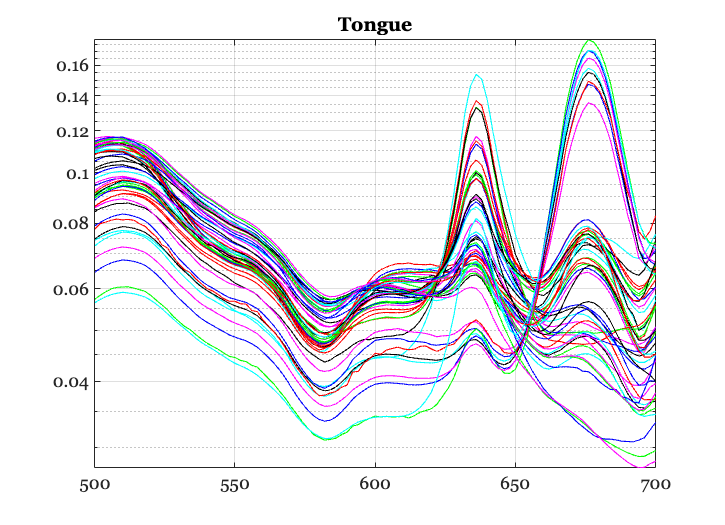

% filesAll = ieTableGet(T,...
%     'substrate','tongue');

filesAll = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Find the dimensionality

Perform SVD explicitly, rather than using the pca() method.

[UT, S, ~] = svd(dataTongue, 'econ');

if criterion < 1
    eigenvalues = diag(S).^2;
    totalVariance = sum(eigenvalues);
    explainedVarianceRatio = eigenvalues / totalVariance;

    % Thresholding
    cumulativeVariance = cumsum(explainedVarianceRatio);
    dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
else
    dimensionality = criterion;

Forcing dimensionality


end

fprintf('Tongue estimated dimensionality: %d\n', dimensionality);

Estimated dimensionality: 4


## Show Tongue fluorescence basis vectors

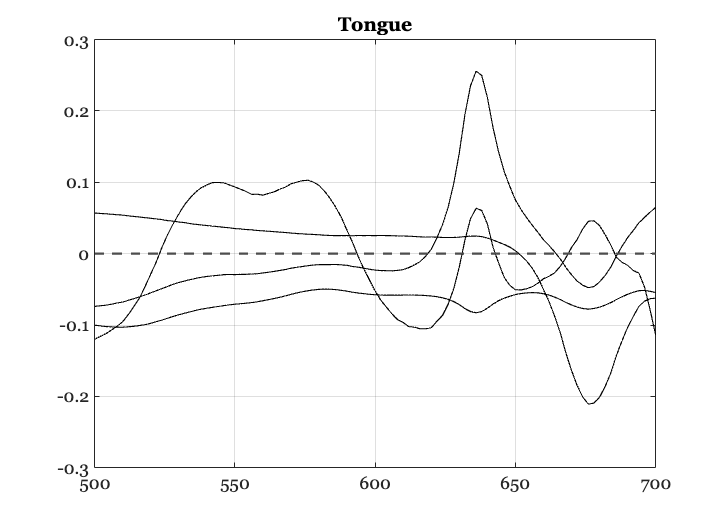

ndim = dimensionality;
UT = UT(:,1:ndim);

% The mean and basis vectors
ieFigure;
plot(waves,UT,'k-');
grid on;
xaxisLine;
title('Tongue');

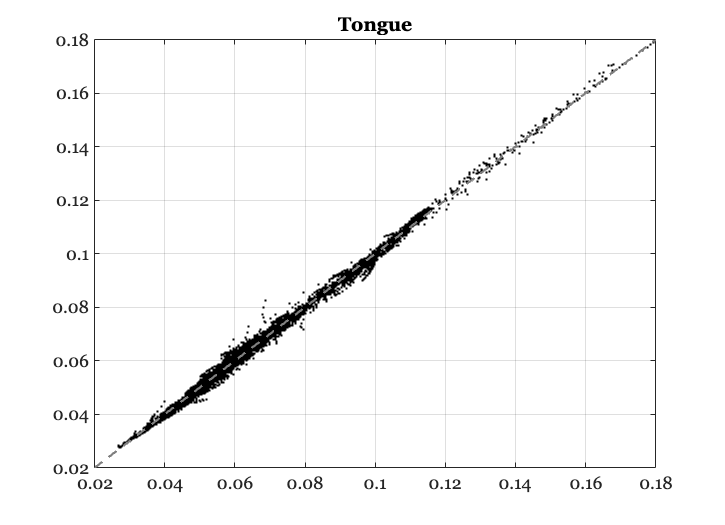


ieFigure;
wgts = UT'*dataTongue;
est = UT*wgts;
plot(est(:),dataTongue(:),'k.');
identityLine;
grid on;
title('Tongue');

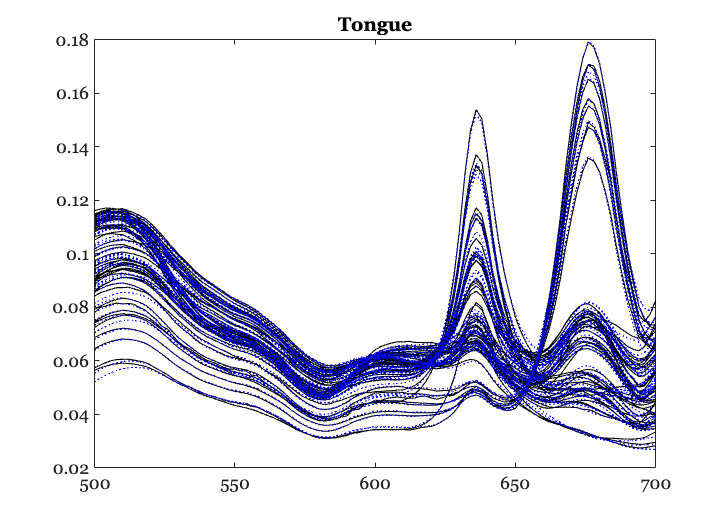


ieFigure;
plot(waves,dataTongue,'k-'); hold on;
plot(waves,est,'b:');
title('Tongue');

## Read the Lip data

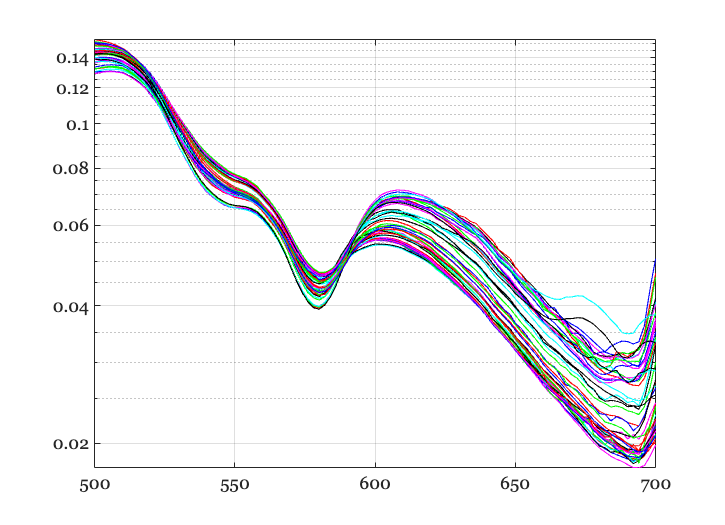

filesAll = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');

dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataLip); grid on;


[UL, S, ~] = svd(dataLip, 'econ');
if criterion < 1
    eigenvalues = diag(S).^2;
    totalVariance = sum(eigenvalues);
    explainedVarianceRatio = eigenvalues / totalVariance;

    % Thresholding
    cumulativeVariance = cumsum(explainedVarianceRatio);
    dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
else
    dimensionality = criterion;
end

fprintf('Estimated dimensionality: %d\n', dimensionality);

Estimated dimensionality: 2


## Compute bases with svd

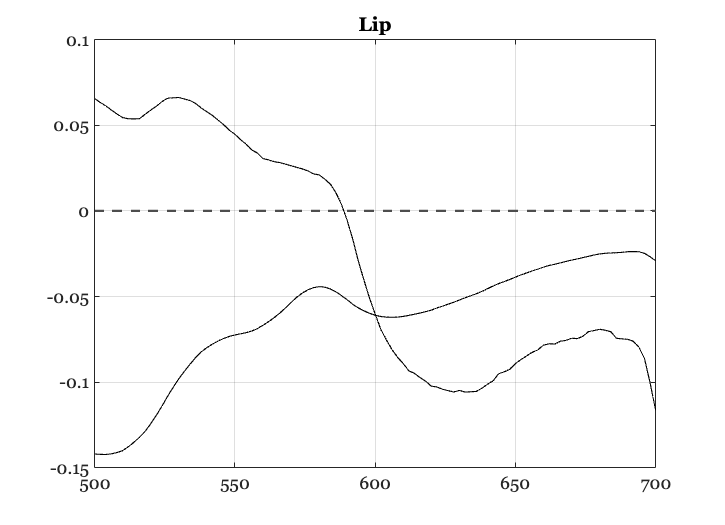

ndim = dimensionality;
UL = UL(:,1:ndim);
ieFigure;
plot(waves,UL,'k-');
grid on;
xaxisLine;
title('Lip');

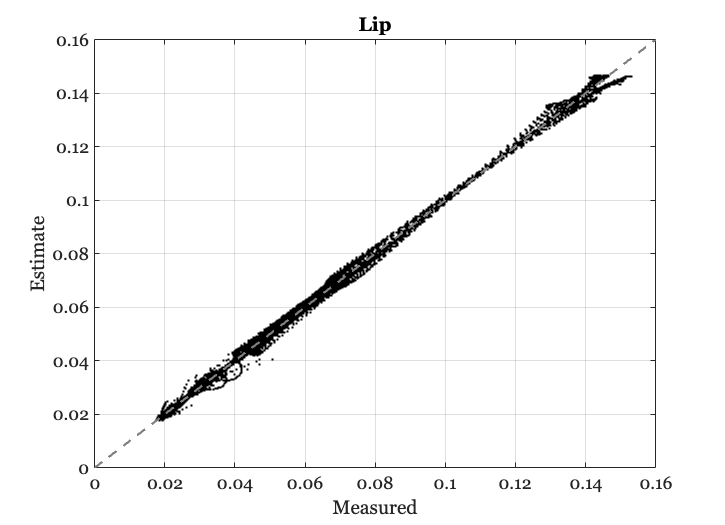


ieFigure;
wgts = UL'*dataLip;
est = UL*wgts;
plot(dataLip(:),est(:),'k.');
identityLine;
grid on; xlabel('Measured'); ylabel('Estimate');
title('Lip');

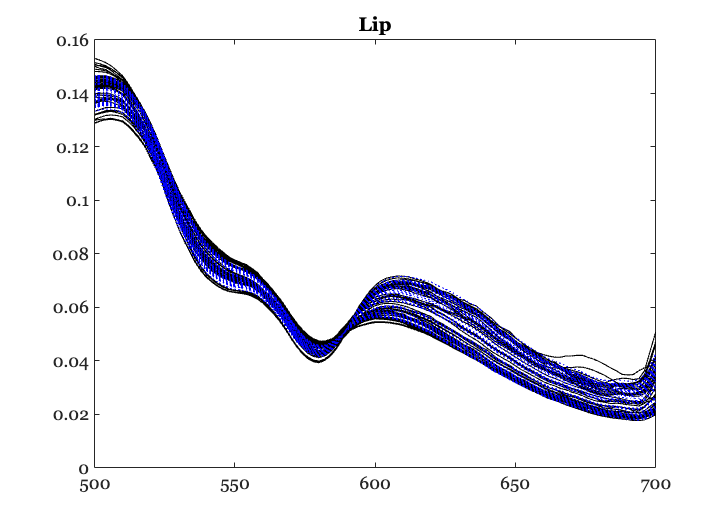


ieFigure;
plot(waves,dataLip,'k-'); hold on;
plot(waves,est,'b:');
title('Lip');

## How similar are the tongue and lip bases?

Also -  How well does collagen-blood and FAD and Porphyrin fit the basis, U? Or the other way around?

How well does collagen-blood and FAD and Porphyrin fit the basis, U? Or the other way around?

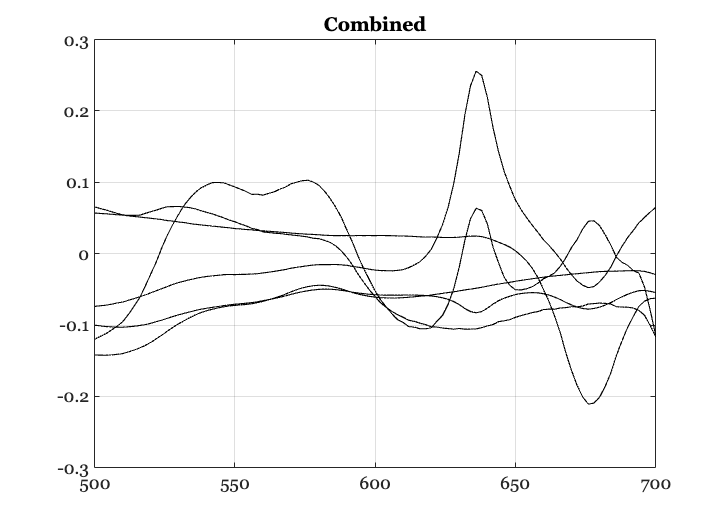

UBoth = cat(2,UL,UT);
ieFigure;
plot(waves,UBoth,'k-'); hold on;
title('Combined')
grid on;


% How much overlap is there between UT and UL?  Can we reduce the
% dimensionality
[UBothR, S, V] = svd(UBoth, 'econ');
if criterion < 1
    eigenvalues = diag(S).^2;
    totalVariance = sum(eigenvalues);
    explainedVarianceRatio = eigenvalues / totalVariance;

    % Thresholding
    cumulativeVariance = cumsum(explainedVarianceRatio);
    dimensionality = find(cumulativeVariance >= criterion, 1, 'first');
else
    dimensionality = criterion;
end

fprintf('Estimated dimensionality: %d\n', dimensionality);


Forcing dimensionality


Estimated dimensionality: 4


## Can we fit the Lip bases using the Tongue bases?

If we think that the tongue has the same fluorophores as the lip, except it also has porphyrin and chlorophyll, then we should be able to predict the lip data as weighted sums of the tongue data.  Or, equivalently, we should be able to predict the lip bases as weighted sums of the tongue bases.


$$U_L =U_T \;w$$


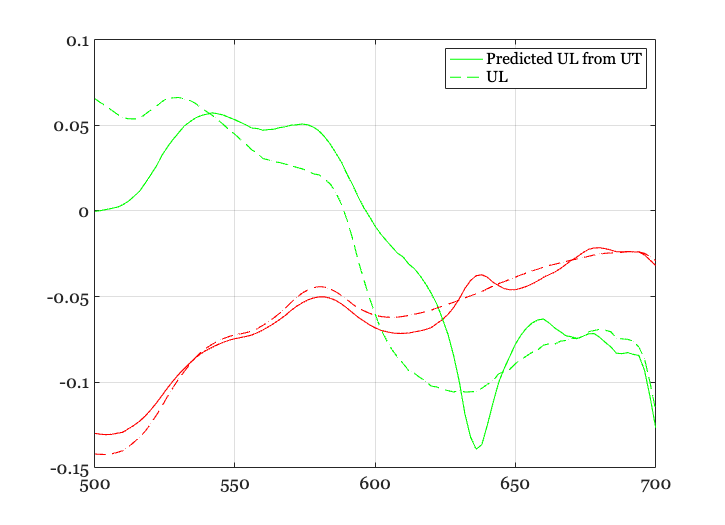

wgts = UT'*UL;
ULpred = UT*wgts;
sym = {'r-','g-','b-','k-'};

ieFigure;
for ii=1:size(ULpred,2)
    hA = plot(waves,ULpred(:,ii),sym{ii}); hold on;
end

sym = {'r--','g--','b--','k--'};
for ii=1:size(UL,2)
    hB = plot(waves,UL(:,ii),sym{ii}); hold on;
end

legend([hA,hB],{'Predicted UL from UT','UL'});
% xaxisLine;
grid on;

## Predict the lip data, $L_d$, from the tongue bases, $U_T$.  

This gives us a numerical sense of the miss compared to the noise in the measurements


$$L_d =U_T \;w$$


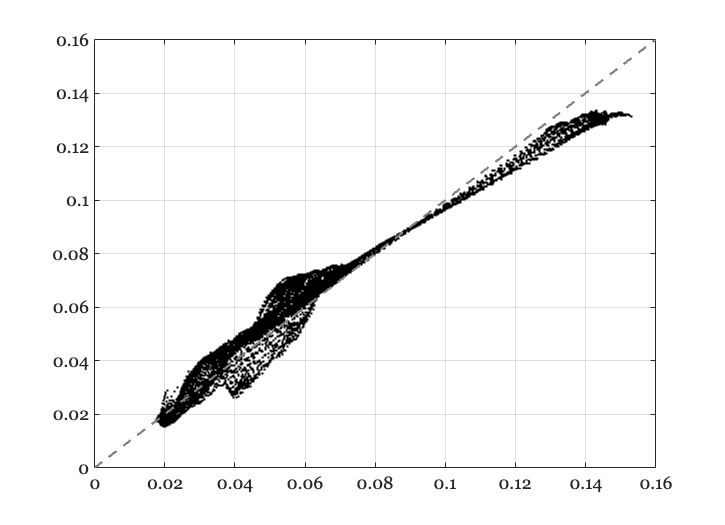

wgts = UT'*dataLip;
dataLipP = UT*wgts;

ieFigure;
plot(dataLip(:),dataLipP(:),'k.');
grid on;
identityLine;

## Is the problem tissue optics?

Suppose that there is a different wavelength filter in the tongue, $D_T$,  and lip, $D_L$.  Then we might have a pair of diagonal matrices that differ for the bases from the lip and tongue fluorophore signals.  We can combine the two diagonal matrices into one


$$D_{L\;} U_L =D_T U_T$$



$$U_L =D\;U_T$$


So a next project is to find a low-dimensional representation of the combined diagonal matrix, $D_\phi$, and search for its parameters, $\phi$ and the weights, $\omega$ that would satisfy


$$U_{L\;} =D_{\phi } U_T \omega$$


Here is a link to Gemini's solution in Matlab:  [https://g.co/gemini/share/1f70dfeefdde](https://g.co/gemini/share/1f70dfeefdde)

Here is the search code written by Gemini that we can check.

function [optimized_params, optimized_S] = solve_uls_matlab(UL, UT, param_func, initial_params, initial_S)
% Solves UL = D UT S, with parameterized D, using optimization.
%
% Args:
%     UL: w x 2 matrix.
%     UT: w x 4 matrix.
%     param_func: Function handle that takes parameters and returns the diagonal of D.
%     initial_params: Initial parameters for D.
%     initial_S: Initial guess for S.
%
% Returns:
%     Optimized parameters and S.

    function error = error_func(x)
        params = x(1:length(initial_params));
        S = reshape(x(length(initial_params) + 1:end), 4, 2);
        D_diag = param_func(params);
        D = diag(D_diag);
        error = norm(UL - D * UT * S, 'fro');
    end

initial_x = [initial_params(:); initial_S(:)]; % Flatten initial parameters and S

options = optimoptions('fminunc', 'Algorithm', 'quasi-newton'); % You can change the algorithm
optimized_x = fminunc(@error_func, initial_x, options);

optimized_params = optimized_x(1:length(initial_params));
optimized_S = reshape(optimized_x(length(initial_params) + 1:end), 4, 2);
end

% Example parameterization (polynomial)
function D_diag = polynomial_param(params)
w = length(UL); % Assuming UL is defined globally in the workspace
indices = 0:(w - 1);
D_diag = polyval(params, indices);
end

% Example usage (assuming UL and UT are already defined in your workspace)
% w = 100;
% UL = rand(w, 2);
% UT = rand(w, 4);

% degree = 3; % degree of the polynomial
% initial_params = rand(degree + 1, 1);
% initial_S = rand(4, 2);

% [params, S] = solve_uls_matlab(UL, UT, @polynomial_param, initial_params, initial_S);

% disp('Optimized Parameters:');
% disp(params);
% disp('Optimized S:');
% disp(S);